# **EllipticCK**

Complementary complete elliptic integral of the first kind 

## Definition


$$\mathit{K'}\left(m\right)\equiv K\left(1-m\right)$$



$$\mathit{\mathbf{K'}}\left(k\right)\equiv \mathit{K'}\left(k^2 \right)$$


where *k *is the modulus, *m *is the parameter.

Domain: $m\ge 0$,(or  $-\infty <k<\infty$). For the specified domain, the  codomain is real numbers.

Special values:

$K\left(0\right)=\infty ,$   $K\left(1\right)=\frac{\pi }{2}$,   $K\left(\infty \right)=0$

## Syntax

Y = EllipticCK(K)

y = elCK(k)

Y = mEllipticCK(M)

y = melCK(m)

## Description

**Y = EllipticCK(K) **returns the value of the complemetary complete elliptic integral of the first kind $\mathit{\mathbf{K'}}\left(k\right)$ for each element of the array  K (modulus).  K must be real array or scalar. **EllipticCK** is the wrapper function which calls the functions **elCK** element-wise via the function **ufun1**.

**y = elCK(k)** returns the value of the complementary complete elliptic integral of the first kind  $\mathit{\mathbf{K'}}\left(k\right)$ for  the modulus k. It is assumed that  k is real scalars without check. y is NaN if k is invalid or convergence failed. **elCK** is the wrapper function which calls the functions **melCK**.

**Y = mEllipticCK(M)** returns the value of  the complementary complete elliptic integral of the first kind $\mathit{K'}\left(m\right)$ for each element of the array  M (parameter).  M must be real array or scalar. **mEllipticCK** is the wrapper function which calls the functions **melCK** element-wise via the function **ufun1**.

**y = melCK(m)** compute value of  the complementary complete elliptic integral of the first kind $\mathit{K'}\left(m\right)$ for  the parameter m. It is assumed that  m is real scalars without check. y is NaN if m is invalid or convergence failed.  **melCK **call the Carlson's function **rf **for calculation of $\mathit{K'}\left(m\right)$ ([1-2]).

## Precision

For  -${10}^6 <m$<1 the relative error of  **melCK **is less than ${10}^{-15}$ .

## **Numerical Examples**

**Scalar input**

format long
k = 0.5 % k >= 0

k = 0.5000

[elCK(k), EllipticCK(k), melCK(k^2), mEllipticCK(k^2)]

ans =    2.156515647499643   2.156515647499643   2.156515647499643   2.156515647499643


m = 0.5; % m >= 0 
[elCK(sqrt(m)), EllipticCK(sqrt(m)), melCK(m), mEllipticCK(m)]

ans =    1.854074677301372   1.854074677301372   1.854074677301372   1.854074677301372


Accuracy. 

fprintf('%.16g\n',elCK(2)) % Maple 18D  1.078257823749821 62

1.078257823749822


Special values

elCK(0)

ans = Inf

disp(elCK(1) - pi/2)

     0



melCK(inf)

ans = 0

elCK(-inf)

ans = 0

Identities

k = sqrt(2)/2

k = 0.7071

disp(elCK(k)-elK(k))

    -2.220446049250313e-16



k = sqrt(2) - 1

k = 0.4142

disp(elCK(k) - sqrt(2)*elK(k))

     0



k = 3 - 2*sqrt(2)

k = 0.1716

disp(EllipticCK(k) - 2*EllipticK(k))

     1.332267629550188e-15



k = 200;
disp(elCK(k)-melCK(k^2))

     0



disp(elCK(k)-elK(sqrt(1-k^2)))

     0



m=200;
disp(melCK(m)-melK(1-m))

     0



[MATLAB example](https://www.mathworks.com/help/symbolic/ellipticck.html)

format short
s = [mEllipticCK(1/2), mEllipticCK(pi/4), mEllipticCK(1),  mEllipticCK(inf)]

s =     1.8541    1.6671    1.5708         0


**Vector input**

k = [-0.2, -0.1, 0.999];
disp(EllipticCK(k)-EllipticK(sqrt(1-k.^2)))

   1.0e-15 *

    0.8882         0         0



**Matrix input**

K=[1/2 1/3 1/4; -1/2 -1/3 -1/4]

K =     0.5000    0.3333    0.2500
   -0.5000   -0.3333   -0.2500


disp(EllipticE(K).*EllipticCK(K)+EllipticCE(K).*EllipticK(K)...
    -EllipticK(K).*EllipticCK(K)-pi/2*ones(size(K)))

   1.0e-15 *

    0.8882         0         0
    0.8882         0         0



## **Graphs**

**Example 1**

[MATLAB example](https://www.mathworks.com/help/symbolic/ellipticck.html)

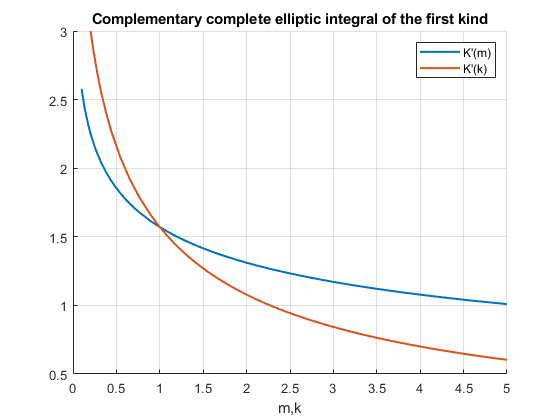

figure
hold on
fplot(@(m) mEllipticCK(m),[0.1, 5], 'LineWidth',1.5)
fplot(@(k) EllipticCK(k),[0.1, 5], 'LineWidth',1.5)
title('Complementary complete elliptic integral of the first kind')
legend('K''(m)','K''(k)')
xlabel('m,k')
ylim([0.5 3])
grid on
hold off

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also